# `Creación del primer modelo de la red neuronal CNN 1`

`Este modelo consiste en una red convolución que se toma de referencia de la propiuesta en el link de MATLAB, esta red no posee capa de maxpooling, únicamente las capas convolucionales con la función de activación ReLU. El tamaño del fiultro es de 5x5 y por cada capa varía la cantidad de filtros. Se cuenta con un padding de 2 lo cual significa que agrega dos pixeles adicionales alrededor de cada borde. `

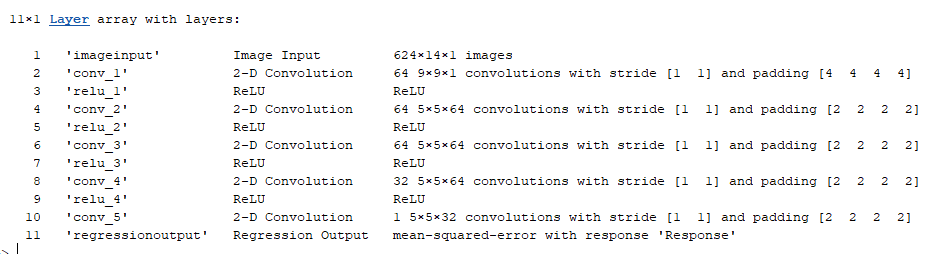

clc; clear all;

enable_Train = true;
data = load("X_train.mat");
label = load("Y_train.mat");

%Se importan los datos y las variables asociadas con los datos para el
%entrenamiento
data = data.x_train;
label = label.y_train;

size(label)

ans =          624          14           2        1000


[subport, simbolos, valor] = size(label)

Enseguida se hace la separación de los datos para hacer la validación cruzada, tomando el 70% de la información obtenida para el entrenamiento y el 30% se usa para la validación.

ratio = 0.75; %Porcentaje para la separación de los datos

[trainId,~,testId] = dividerand(1000,ratio,0.0,1-ratio);

x_train = data(:,:,:,trainId);
y_train = label(:,:,:,trainId);

x_val = data(:,:,:,testId);
y_val = label(:,:,:,testId);



size(y_train)

ans =    624    14     2   750


size(y_val)

ans =    624    14     2   250


size(x_val)

ans =    624    14     2   250


En este fragmento de código se hace una separación de la componente real y la imaginaria, para que de esta forma el número de muestras se multiplique por dos: [624 14 1 700] para la real y [624 14 1 700] para la componente imaginaria.

x_train = cat(4, x_train(:,:,1,:), x_train(:,:,2,:));
y_train = cat(4, y_train(:,:,1,:), y_train(:,:,2,:));

x_test = cat(4, x_val(:,:,1,:), x_val(:,:,2,:));
y_test = cat(4, y_val(:,:,1,:), y_val(:,:,2,:));


size(x_train)

ans =          624          14           1        1500


size(y_train)

ans =          624          14           1        1500



size(x_test)

ans =    624    14     1   500


size(y_test)

ans =    624    14     1   500


Este fragmento del código se usa para la gneración del modelo de Deep Learning que va a ser usado para la estimación del canal.

rng(42);

if enable_Train
    batch = 32; % Es el número de ejemplos que se introducen en la red.
    
    %Esta variable se usa para verificar 5 veces en cada época.
    valFrequency = round(size(x_train,4)/batch/5); 


    %Aquí se puede definir las capas que van a componer la RNA

    capas = [
        imageInputLayer([subport simbolos 1],'Normalization','none')
        convolution2dLayer(9,64,'Padding',4)
        reluLayer
        convolution2dLayer(5,64,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(5,64,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(5,32,'Padding',2,'NumChannels',64)
        reluLayer
        convolution2dLayer(5,1,'Padding',2,'NumChannels',32)
        regressionLayer
    ]


    hiper_param = trainingOptions('adam', ...
        'InitialLearnRate',3e-4, ...
        'MaxEpochs',5, ...
        'Shuffle','every-epoch', ...
        'Verbose',false, ...
        'Plots','training-progress', ...
        'MiniBatchSize',batch, ...
        'ValidationData',{x_test, y_test}, ...
        'ValidationFrequency',valFrequency, ...
        'ValidationPatience',5);


    [estimacionRNA, infoRNA] = trainNetwork(x_train, ...
        y_train,capas,hiper_param);

    %save('Modelo1.mat', "estimacionRNA");

else
    load("Modelo1.mat");
end

capas =   11×1 Layer array with layers:

     1   ''   Image Input         624×14×1 images
     2   ''   2-D Convolution     64 9×9 convolutions with stride [1  1] and padding [4  4  4  4]
     3   ''   ReLU                ReLU
     4   ''   2-D Convolution     64 5×5×64 convolutions with stride [1  1] and padding [2  2  2  2]
     5   ''   ReLU                ReLU
     6   ''   2-D Convolution     64 5×5×64 convolutions with stride [1  1] and padding [2  2  2  2]
     7   ''   ReLU                ReLU
     8   ''   2-D Convolution     32 5×5×64 convolutions with stride [1  1] and padding [2  2  2  2]
     9   ''   ReLU                ReLU
    10   ''   2-D Convolution     1 3×3×32 convolutions with stride [1  1] and padding [2  2  2  2]
    11   ''   Regression Output   mean-squared-error

Error using trainNetwork
Invalid training data. The output size ([626 16 1]) of the last layer does not match the response size ([624 14 1]).